#  Chapter 6 - State Space Design of Control Systems 

##  Section 7 - Observer Controllers

clear all; clc

**Notes: **

Transfer Function of the observer-based controller: Assume the plant is completely observable and that we will use observed-state feedback control, u = -Kx. 

## 6-10 : Consider the design of a regulator system

Step 1: Plant dynamics

A = [ 0 1; 20.6 0];
B = [0; 1];
C = [1 0];

Step 2: Use pole-placement approach to determine state-feedback gain matrix, K, based on desired closed-loop poles

K = [29.6 3.6];

Step 3: Use desired observer poles to determine observer gain matrix, Ke 

Ke = [16; 84.6];

Step 4: Obtain TF of observer controller - full-order observer

% define observer state-space equations using characterisic equation
AA = A - Ke*C - B*K;
BB = Ke;
CC = K;
DD = 0;

[num, den] = ss2tf(AA, BB, CC, DD);
tf_observer = tf(num, den)


tf_observer =
 
     778.2 s + 3691
  --------------------
  s^2 + 19.6 s + 151.2
 
Continuous-time transfer function.



Step 5: Determine the system response using the given initial conditions. 

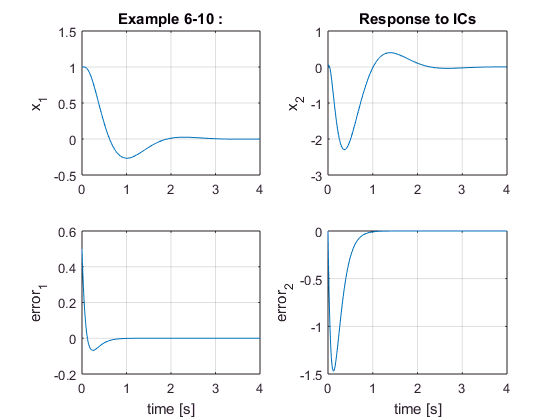

% Define controller/plant dynamics 
sys = ss([A - B*K B*K; zeros(2,2) A-Ke*C], eye(4), eye(4), eye(4));

% Initial conditions
z = initial(sys, [1; 0; 0.5; 0]);
z2 = eye(4)*z';
t = linspace(0, 4, size(z,1));

% Plot
subplot(221); plot(t, z2(1,:)), grid
title('Example 6-10 :'), ylabel('x_1')
subplot(222); plot(t, z2(2,:)), grid
title('Response to ICs'), ylabel('x_2')
subplot(223); plot(t, z2(3,:)), grid
ylabel('error_1'), xlabel('time [s]')
subplot(224); plot(t, z2(4,:)), grid
ylabel('error_2'), xlabel('time [s]')

The position and error of the system approach zero during the response to initial conditions. 

Design of regulator system with observer: 

- Derive the plant TF : [num, den] = ss2tf(A, B, C, D)

- Choose the desired closed-loop poles for pole placement. Choose the desired observed poles. ( J and L)

- Determine the state feedback gain matrix, K, and observer gain matrix, Ke

- Using K and Ke, find observer-controller TF. If it is a stable controller, check the response to initial conditions. If the response is not acceptable, adjust the closed-loop pole locations and/or observer pole locations until an acceptable response is obtained.

## 6-11 Design both the full-order and minimum-order observers for the plant.

clear all; clc

Assume the desired closed-loop poles for the pole-placement are given. Compare the responses of the full-order and min-order observers to initial conditions. Also compare the bandwidth of both systems. 

Step 1: Derive the plant TF

A = [0 1; 0 -2];
B = [0; 4];
C = [1 0];

Step 2: Choose desired poles (Given)

% Closed-Loop 
J = [-2 + j*2*sqrt(3) -2 - j*2*sqrt(3)];

% Observer Poles
L_full = [-8 -8];
L_min = [-8];

Step 3: Determine gain matrices, K and Ke

K = acker(A, B, J);

Ke_full = acker(A', C', L_full')

Ke_full =     14    36


Step 4a: Determine observer-controller TF for Full-Order Observer

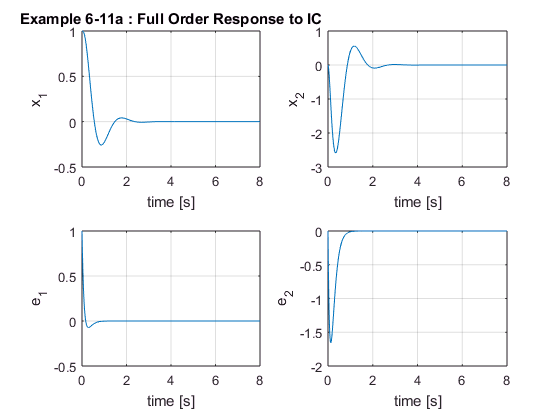

AA = [A-B*K B*K; zeros(2,2) A-Ke_full'*C];
sys = ss(AA, eye(4), eye(4), eye(4));

% Response to Initial Conditions
t = 0:0.01:8;
x = initial(sys, [1; 0; 1; 0], t);
x2 = eye(4)*x';

% Plot
figure
subplot(221); plot(t, x2(1,:)), grid
title('Example 6-11a : Full Order Response to IC')
xlabel('time [s]'), ylabel('x_1')
subplot(222); plot(t, x2(2,:)), grid
xlabel('time [s]'), ylabel('x_2')
subplot(223); plot(t, x2(3,:)), grid
xlabel('time [s]'), ylabel('e_1')
subplot(224); plot(t, x2(4,:)), grid
xlabel('time [s]'), ylabel('e_2')

The pole-placement was appropriate for the system. The response to the initial conditions approached zero in an adequate amount of time. Now need to verify that the TF is stable. 

[num, den] = ss2tf(A-Ke_full'*C-B*K, Ke_full', K, 0);
full_order_tf = tf(num, den)


full_order_tf =
 
     74 s + 256
  ----------------
  s^2 + 18 s + 108
 
Continuous-time transfer function.



Based on the TF, the system is stable. 

Step 4b: Determine the response of the minimum-order observer 

%Obtain Ke_min
Aab = [1];
Abb = [-2];
Ke_min = acker(Abb', Aab', L_min)

Ke_min = 6

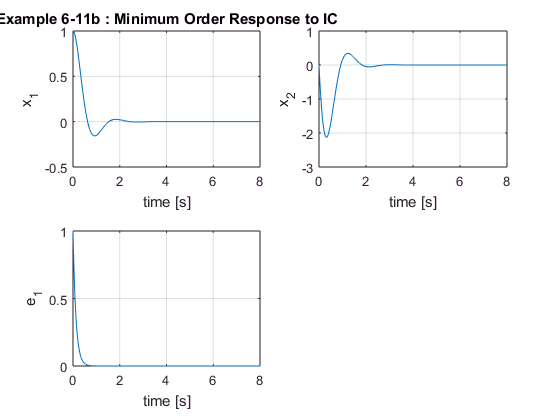


% Define system
Kb = 0.5;
AA = [A - B*K B*Kb; zeros(1,2) Abb - Ke_min*Aab];
sys2 = ss(AA, eye(3), eye(3), eye(3));

% Response to IC
t = 0:0.01:8;
z = initial(sys2, [1; 0; 1], t);
z2 = eye(3)*z';

% Plot
figure
subplot(221); plot(t, z2(1,:)), grid
title('Example 6-11b : Minimum Order Response to IC')
xlabel('time [s]'), ylabel('x_1')
subplot(222); plot(t, z2(2,:)), grid
xlabel('time [s]'), ylabel('x_2')
subplot(223); plot(t, z2(3,:)), grid
xlabel('time [s]'), ylabel('e_1')

The minimum order observer controller performed very similar to the full order observer. 

Verify that the TF is stable. 

% Did quite follow how this was derived... 
Aaa = 0; Aab = 1; Aba = 0; Abb = -2;
Ba = 0; Bb = 4;
Ka = 4; Kb = 0.5;
Ke = 6;
Ahat = Abb - Ke*Aab;
Bhat = Ahat * Ke + Aba - Ke*Aaa;
Fhat = Bb - Ke*Ba;
Atil = Ahat - Fhat*Kb;
Btil = Bhat - Fhat*(Ka + Kb*Ke);
Ctil = -Kb;
Dtil = -(Ka + Kb*Ke);

[num2, den2] = ss2tf(Atil, Btil, -Ctil, -Dtil);
min_order_tf = tf(num2, den2)


min_order_tf =
 
  7 s + 32
  --------
   s + 10
 
Continuous-time transfer function.



Step 4c: Compare the response of both methods

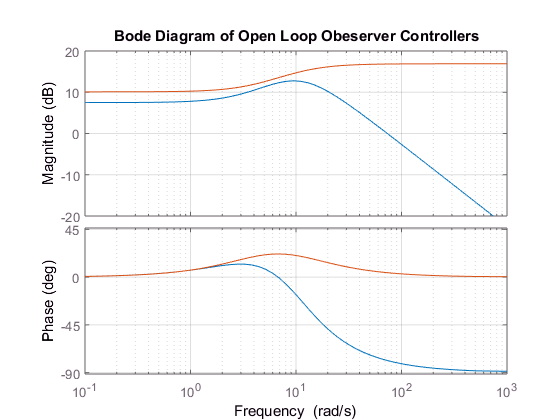

figure 
bode(num, den)
hold on
bode(num2, den2), grid
title(' Bode Diagram #1: Open Loop Obeserver Controllers')
legend('Full', 'Minimum')
hold off

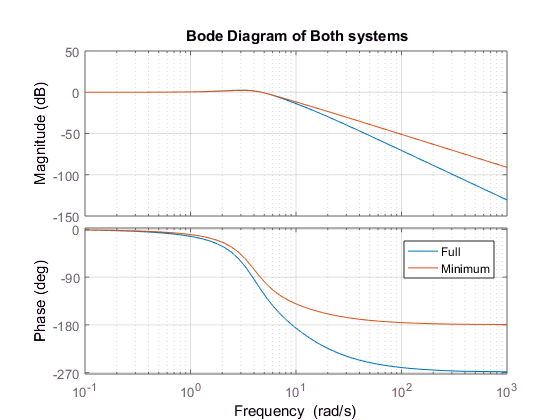


figure
bode([296 1024], [1 20 144 512 1024])
hold on 
bode([28 128], [1 12 48 128]), grid
title(' Bode Diagram #2: Closed Loop of Both Systems')
legend('Full', 'Minimum')
hold off

Based on Bode Diagram #1, the obeserver controller is clearly a lead compensator. The bandwidth of the minimum-order observer-controller is wider than the full order. The full order system has a better high-frequency noise-rejection characteristic than the minimum order. 